# Total Variation Image Completion Demo

Stephen Becker, June 2018  for CCIMI short-course on optimisation

## Load true image

Load the Modified Shepp Logan phantom test image, often used for MRI and inverse imaging problems

(In Matlab, you can make this image of arbitrary size using a command; in Python, you can load the test images we saved to file in either .mat format (use scipy.io.loadmat), or an ascii array (whitespace separator) or the png)

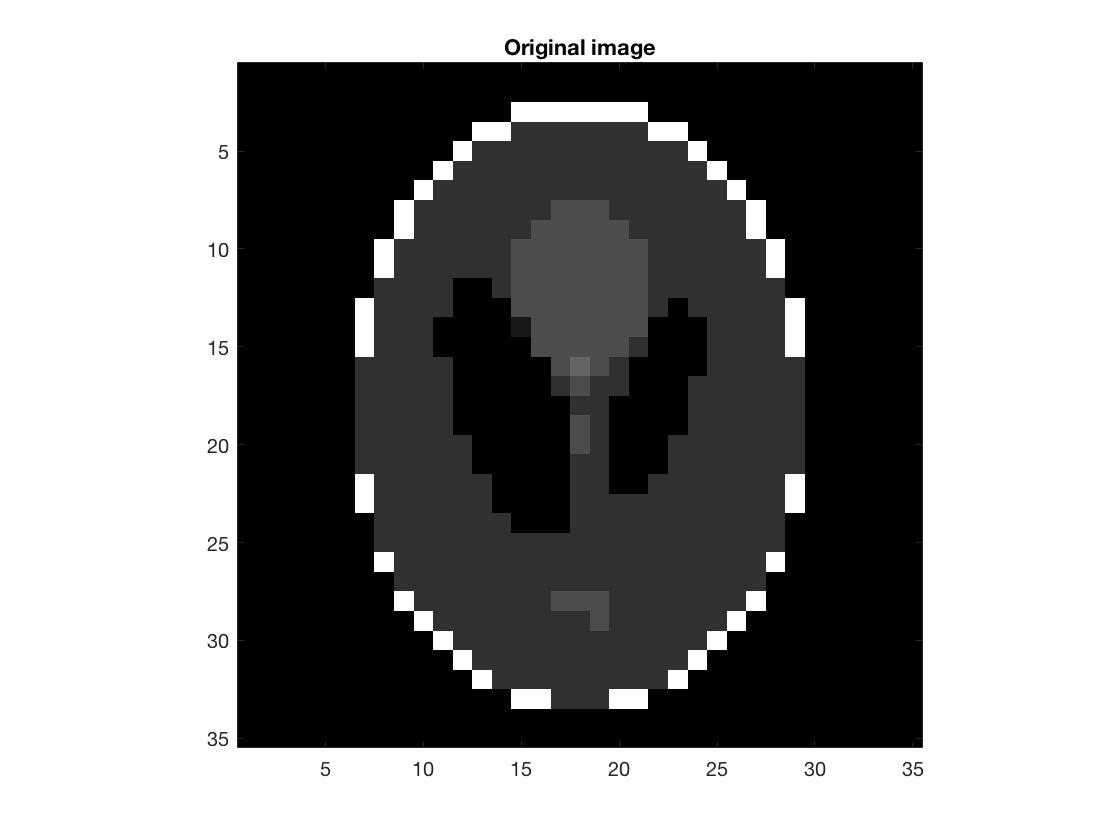

n1     = 35; % make sure it is odd
n2     = n1;
TrueImage   = phantom('Modified Shepp-Logan',n1); % values are in [0,1]
clf; imagesc(TrueImage); colormap gray; title('Original image'); axis image

## Take some measurements in the Fourier domain

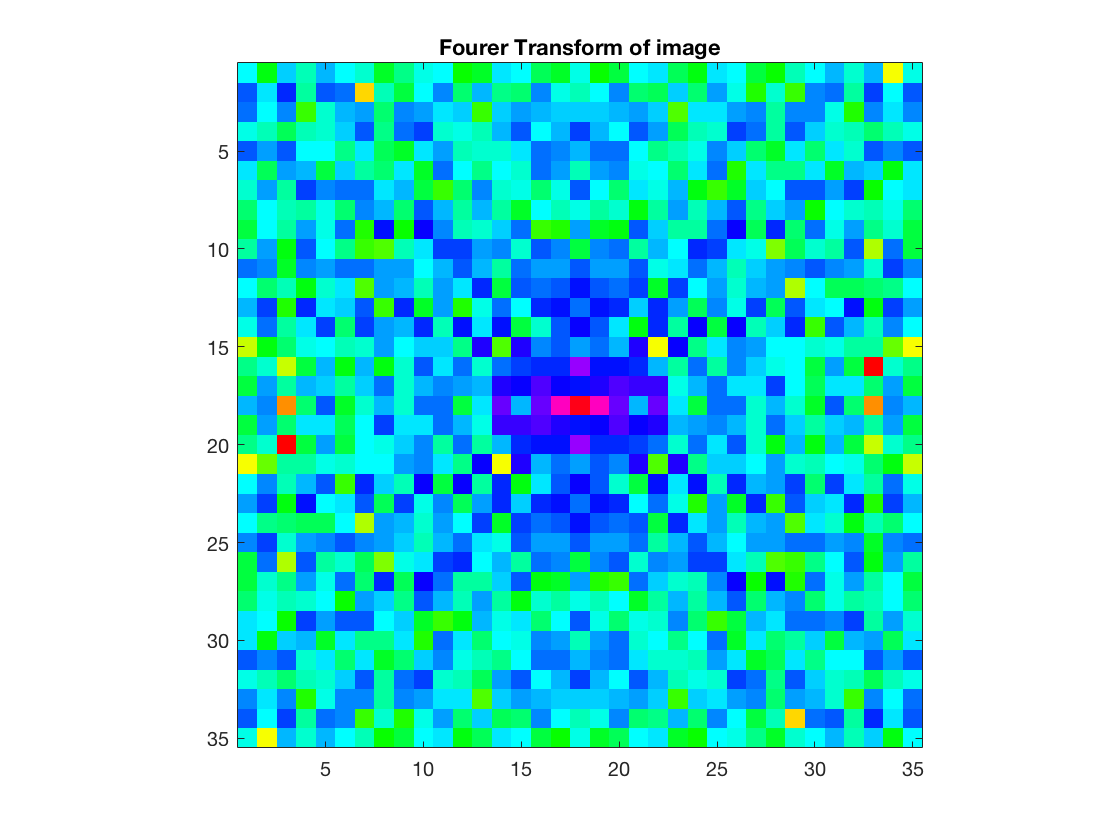

Yhat = fft2( TrueImage );
figure(1); clf;
imagesc( fftshift(log10(abs(Yhat))) ); axis square; colormap hsv; title('Fourer Transform of image')

% Now, sample some of the Fourier components, but sample more low-frequency
% We will only work with 1 quadrant (others come via symmetry)
nn     = (n1-1)/2; % assume n1 is odd
[X,Y] = meshgrid( linspace(0,1,(n1-1)/2)); % upper right quadrant
rad   = sqrt( X.^2 + Y.^2); % radius
rng(1);     % make this reproducible
randDraw     = rand(nn,nn)./rad;
samp         = (randDraw > .9 );
% add in other quadrants
samp         = [fliplr(samp),zeros(nn,1),samp];
binarySamples= [ flipud(samp); zeros(1,n1); samp];
binarySamples(nn+1,nn+1) = 1; % keep the DC component
fprintf('Keeping %d of %d possible Fourier samples (%g%%)\n',...
    nnz(binarySamples), n1*n2, 100*nnz(binarySamples)/(n1*n2) );

Keeping 381 of 1225 possible Fourier samples (31.102%)


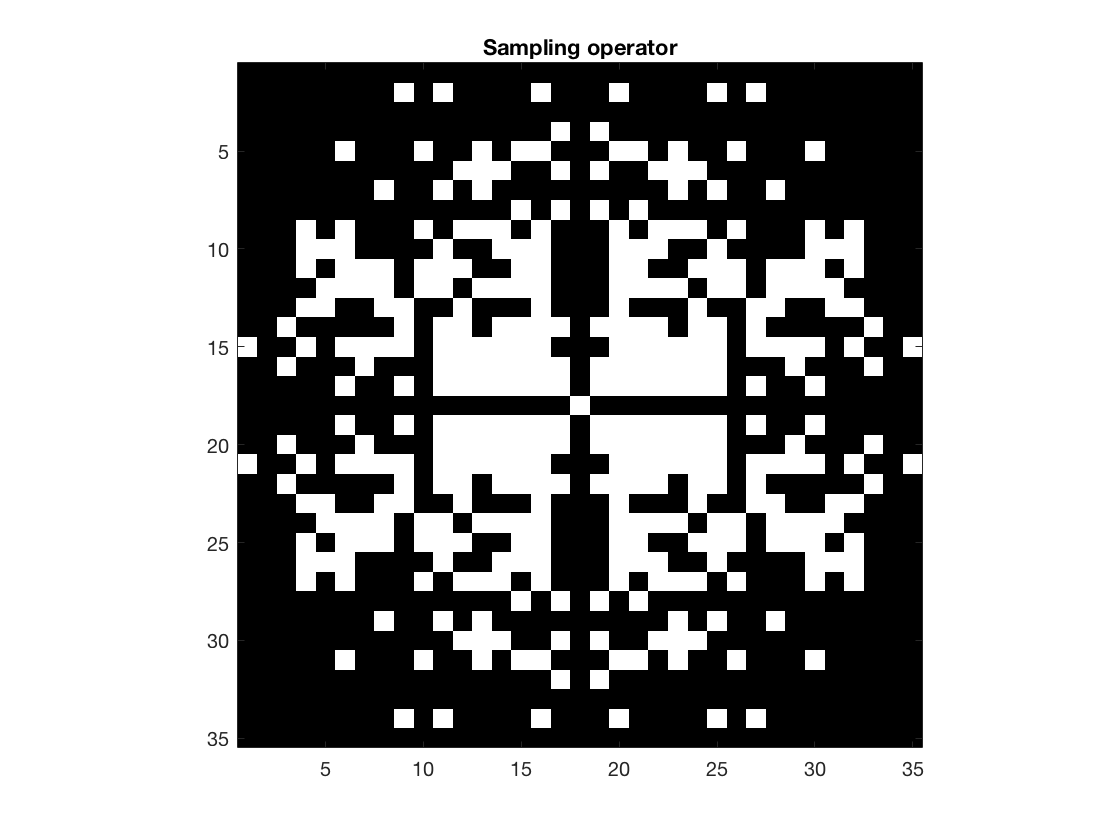

figure(2); clf;
imagesc( binarySamples ); axis image; colormap gray; title('Sampling operator')

binarySamples2     = ifftshift( binarySamples );
samples            = find( binarySamples2 );
samplingOp         = @(x) x(samples);
observationOp      = @(I) samplingOp( vec(fft2(I)));
data               = observationOp( TrueImage );

## Naive recovery from the samples: set unobserved Fourier coefficients to zero

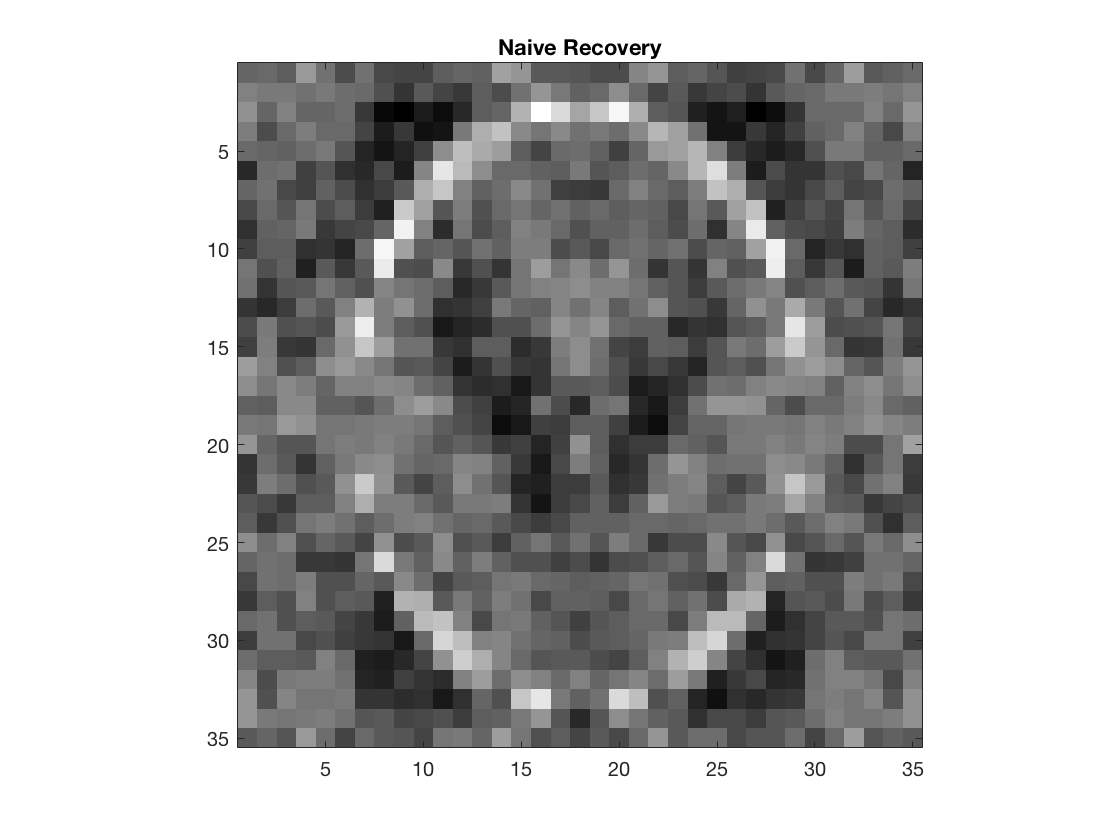

Yhat     = zeros(n1,n2);
Yhat( samples ) = data;
ImageRecovered     = ifft2( Yhat );
clf; imagesc(ImageRecovered); colormap gray; title('Naive Recovery'); axis image

## CVX doesn't understand that fft2() is a linear operator. Convert it to a matrix

This is one of the fundamental drawbacks of CVX compared to first-order methods: it needs explicit matrices (either sparse or dense)

A     = zeros(length(data),n1*n2);
e     = zeros(n1,n2);
tic
for i = 1:n1*n2
    e(i) = 1;
    A(:,i) = observationOp(e);
    e(i) = 0;
end
toc

Elapsed time is 0.187439 seconds.


## Make the finite difference operators

diff_V  = spdiags( [-ones(n1,1),ones(n1,1)], [0,1], n1, n1 );
D_V     = kron( eye(n2), diff_V );

diff_H  = spdiags( [-ones(n2,1),ones(n2,1)], [0,1], n2, n2 );
D_H     = kron( diff_H, eye(n1) );

TV       = @(X) norm( D_V*X(:) + 1i*D_H*X(:), 1 ); % complex l1-norm

In cvxpy in Python, the l1 norm doesn't handle complex numbers as well, so we can do the following:

TV_alternative     = @(X) sum( norms( [D_V*X(:), D_H*X(:)], 2, 2 ) )

TV_alternative = function_handle with value:
    @(X)sum(norms([D_V*X(:),D_H*X(:)],2,2))


where norms( Y, p, dim) means take the lp norm of each column/row of Y (column if dim=1, row if dim=2), and then we want to sum all of this together.

Some evidence that the two TV definitions are the same:

X     = randn(n1,n2);
abs( TV(X) - TV_alternative(X) )

ans = 0

## Solve image-recovery via CVX

Takes about 3 minutes

tic
cvx_begin
    cvx_solver sdpt3
    variable x(n1,n2)
    minimize TV(x)
    subject to
        x >= 0
        x <= 1
        A*vec(x) == data
cvx_end

 
Calling SDPT3 4.0: 6547 variables, 2450 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 2450
 dim. of socp   var  = 3675,   num. of socp blk  = 1225
 dim. of linear var  = 2450
 dim. of free   var  = 422
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+02|7.0e+00|1.2e+07| 6.079131e+04| 0:0:09|1.2e+07|1.0e+00|1.0e+00| spchol 1   1
 1|0.005|0.005|1.1e+02|7.0e+00|1.2e+07| 5.812323e+04| 0:0:19|1

X     = reshape(x,n1,n2);
toc

Elapsed time is 210.048944 seconds.


## Plot recovered solution

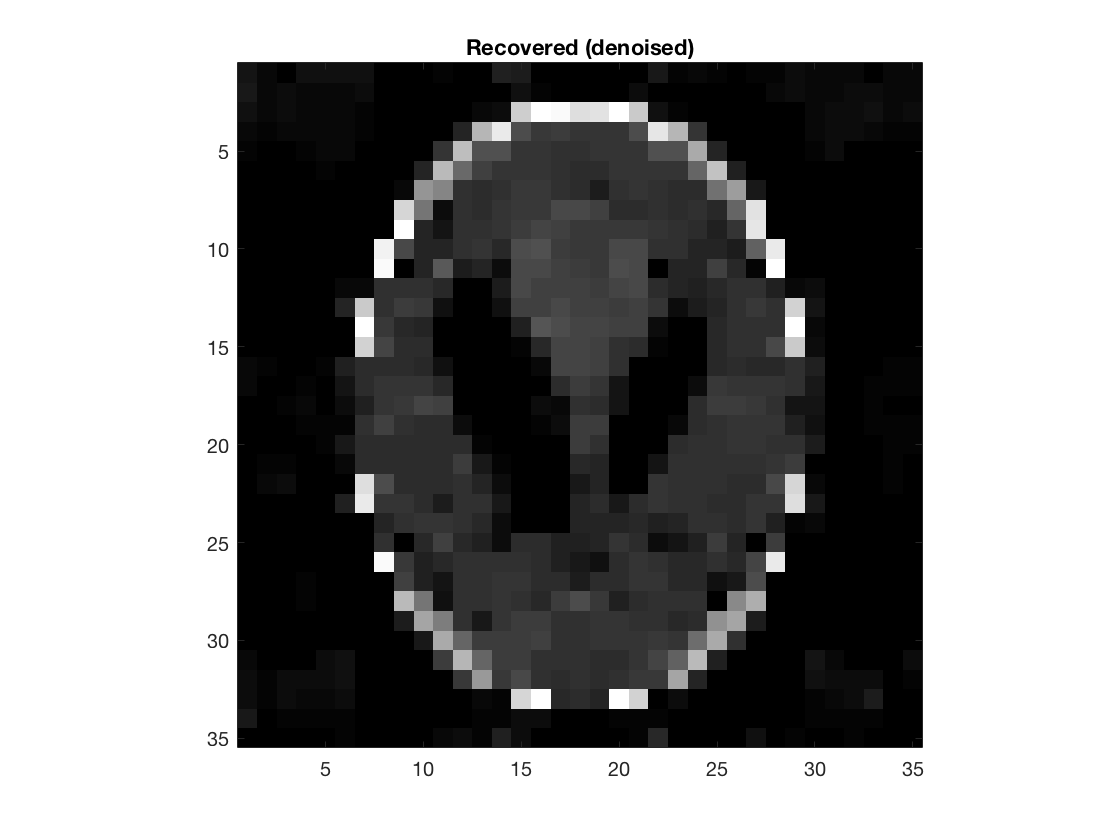

imagesc(X); colormap gray; title('Recovered (denoised)');axis image